e = "20190504_E1"

e = "20190504_E1"

file= "/Users/dvarelat/Documents/MASTER/TFM/DATA/RESULTS/membranes/GASP_PNAS/20190504_E1_mGFP_XYZ_predictions_GASP.nii.gz"

file = "/Users/dvarelat/Documents/MASTER/TFM/DATA/RESULTS/membranes/GASP_PNAS/20190504_E1_mGFP_XYZ_predictions_GASP.nii.gz"

pixelSize = 0.757206; 
voxelDepth = 0.995703;
voxelSize = (pixelSize^2)*voxelDepth;

img = niftiread(file);

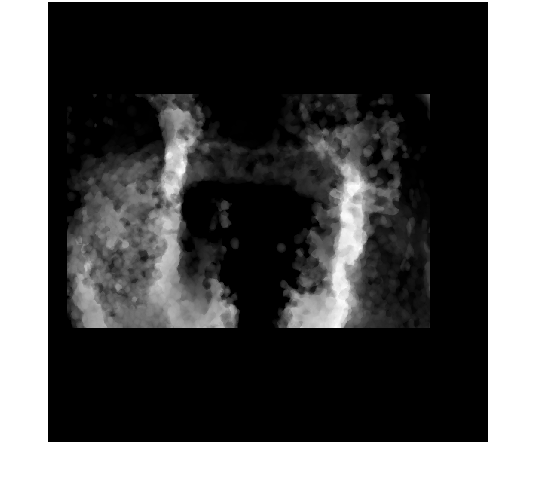

figure                                                              
imshow(sum(img,3),[])                                         
title('Ilastik prediction map, z-projection')      

stats = regionprops3(img,'all');

V = stats(:,"Volume");
V = V{:,:};

CellVolumes = stats.Volume; 

stats([1,2,3,4,5,6,7,8],:) = [];

CellVolumes          = stats.Volume;                   % cell volumes
CellSurfaceAreas     = stats.SurfaceArea;              % cell surface area
CellCentroids        = stats.Centroid;                 % cell centroids
CellVolSurfAreaRatio = CellVolumes./CellSurfaceAreas;  % cell volume-surface area ratio
CellEllipticity      = (stats.PrincipalAxisLength(:,1) - stats.PrincipalAxisLength(:,3))./(stats.PrincipalAxisLength(:,1)); % ellipticity
LongestAxis          = stats.PrincipalAxisLength(:,1); % length of the longest axis (diameter of longest axis)
CellElongation       = LongestAxis./((stats.PrincipalAxisLength(:,2).*stats.PrincipalAxisLength(:,3))./2);
NumberOfCells        = size(stats.Volume,1);           % number of cells

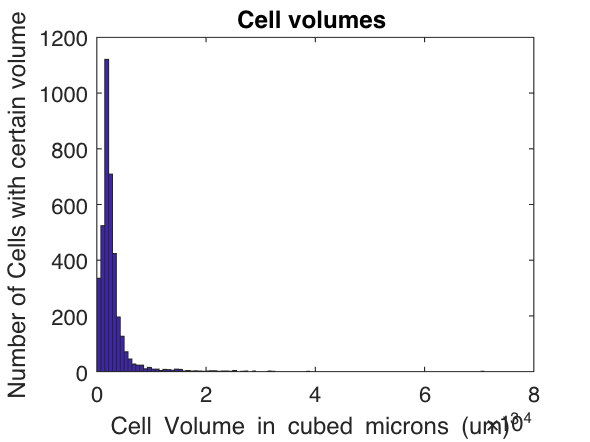

figure                                                              
hist(CellVolumes*voxelSize,100)
title('Cell volumes ') % write here number of cells
ylabel('Number of Cells with certain volume')
xlabel('Cell Volume in cubed microns (um)^3')

% 10.1) All the parameter values
stats_matrix_all      = zeros(NumberOfCells,5);                    
stats_matrix_all(:,1) = CellVolumes;                % parameter 1: volume              
stats_matrix_all(:,2) = CellVolSurfAreaRatio;       % parameter 2: vol-surfArea ratio              
stats_matrix_all(:,3) = CellEllipticity;            % parameter 3: ellipticity          
stats_matrix_all(:,4) = CellElongation;             % parameter 4: elongation
stats_matrix_all(:,5) = LongestAxis;                % parameter 5: the length of the longest axis
%zscored               = zscore(stats_matrix_MEMB_all);  

% 10.2) Knock out some parameters, six possibilities we may look:
stats_matrix_1thru2    = stats_matrix_all(:,1:2);      % parameters 1 and 2
stats_matrix_1thru3    = stats_matrix_all(:,1:3);      % parameters 1, 2 and 3   
stats_matrix_1thru4    = stats_matrix_all(:,1:4);      % parameters 1, 2, 3 and 4
stats_matrix_2thru5    = stats_matrix_all(:,2:5);      % parameters 2, 3, 4 and 5
stats_matrix_3thru5    = stats_matrix_all(:,3:5);      % parameters 3, 4 and 5
stats_matrix_4thru5    = stats_matrix_all(:,4:5);      % parameters 4 and 5
stats_matrix_1and3and4 = stats_matrix_all(:,[1,3,4]);  % parameters 1, 3 and 4
stats_matrix_1and4     = stats_matrix_all(:,[1,4]);    % parameters 1 and 4
stats_matrix_1and3     = stats_matrix_all(:,[1,3]);    % parameters 1 and 3

% 10.3) zscore all of these partial number of spatial parameters:
zscored_1thru2    = zscore(stats_matrix_1thru2); 
zscored_1thru3    = zscore(stats_matrix_1thru3);
zscored_1thru4    = zscore(stats_matrix_1thru4);
zscored_2thru5    = zscore(stats_matrix_2thru5);
zscored_3thru5    = zscore(stats_matrix_3thru5);
zscored_4thru5    = zscore(stats_matrix_4thru5);
zscored_1and3and4 = zscore(stats_matrix_1and3and4);
zscored_1and4     = zscore(stats_matrix_1and4);
zscored_1and3     = zscore(stats_matrix_1and3);

parameters           = {'Cell Volume','Cell Volume/Surface ratio','Cell Ellipticity','Cell Elongation','Longest Axis'};
parameters_1thru2    = {'Cell Volume','Cell Volume/Surface ratio'};
parameters_1thru3    = {'Cell Volume','Cell Volume/Surface ratio','Cell Ellipticity'};
parameters_1thru4    = {'Cell Volume','Cell Volume/Surface ratio','Cell Ellipticity','Cell Elongation'};
parameters_2thru5    = {'Cell Volume/Surface ratio','Cell Ellipticity','Cell Elongation','Longest Axis'};
parameters_3thru5    = {'Cell Ellipticity','Cell Elongation','Longest Axis'};
parameters_4thru5    = {'Cell Elongation','Longest Axis'};
parameters_1and3and4 = {'Cell Volume','Cell Ellipticity','Cell Elongation'};
parameters_1and4     = {'Cell Volume','Cell Elongation'};
parameters_1and3     = {'Cell Volume','Cell Ellipticity'};

%heatm_all       = clustergram(zscored','RowLabels',parameters','ColumnPDist','cosine','RowPdist','cosine','DisplayRange',3,'Colormap',redbluecmap,'Cluster',3);
heatm_3thru5    = clustergram(zscored_3thru5','RowLabels',parameters_1thru4','ColumnPDist','cosine','RowPdist','cosine','DisplayRange',3,'Colormap',redbluecmap,'Cluster',3);

'redbluecmap' requires Bioinformatics Toolbox.